**Universidad Nacional Autónoma de México - Facultad de Ingeniería - Profesor: M.I. Erik Peña Medina**

# Proyecto:Introducción al Modelado Espacial de Robots

**Alumnos:**

**Cruz Zamora Franco Sebastián **

**Franco Ayala Carlos Alfonso**

**Manzano Martinez Nancy**

**Nava Hernández Gerardo Saúl **

**Ortiz Carreño Fabian**

## Resumen

El presente proyecto tiene como objetivo el desarrollo del modelo dinámico completo de un robot manipulador de 3 grados de libertad (3R) tipo RoArm, empleando el formalismo de Euler-Lagrange como herramienta matemática principal. Este tipo de modelado es fundamental en robótica, ya que permite conocer las fuerzas y pares necesarios para controlar el movimiento del robot en el espacio tridimensional, considerando tanto los efectos inerciales como los gravitacionales y las fuerzas de Coriolis.

**Obtención de parámetros:**Como primera etapa, se extrajeron las propiedades físicas de cada uno de los eslabones que conforman el robot directamente desde el software de diseño asistido por computadora Autodesk Inventor, haciendo uso de la herramienta de Propiedades Físicas (iProperties). Los parámetros obtenidos incluyen la masa de cada eslabón, las coordenadas del centro de gravedad en los tres ejes, y los momentos másicos de inercia respecto al centro de gravedad (Ixx, Iyy, Izz). Dado que el modelo dinámico requiere que los centros de masa estén expresados en coordenadas relativas a cada articulación y no al origen global del ensamble, se realizó una corrección de los valores del centro de gravedad en el eje Z, restando el offset correspondiente a la posición de cada motor medido desde la base del robot. Todas las unidades fueron convertidas al Sistema Internacional (kilogramos, metros, segundos).

**Modelado cinemático de posición:** En la segunda etapa se construyó el modelo cinemático del robot mediante transformadas homogéneas, siguiendo la convención de rotaciones ZYX. Se definieron las matrices de transformación entre cada par de eslabones consecutivos (T₀₁, T₁₂, T₂₃, T₃ₚ), y mediante su producto encadenado se obtuvo la transformada total T₀ₚ que describe la posición y orientación del efector final respecto a la base. A partir de esta transformada se extrajo el vector de postura del robot y el vector de posición del efector final p₀ₚ.

**Modelado cinemático de velocidades: **Se calculó el Jacobiano geométrico del robot J(θ) mediante diferenciación del vector de posición respecto a las coordenadas generalizadas. El determinante del Jacobiano fue evaluado simbólicamente para identificar las configuraciones singulares del robot, es decir, aquellas posiciones en las que el robot pierde uno o más grados de libertad. Adicionalmente se calcularon las velocidades angulares de cada eslabón mediante propagación desde la base hasta el efector final.

**Modelado dinámico Mediante Euler-Lagrange:** En la etapa central del proyecto se aplicó el formalismo de Lagrange para obtener las ecuaciones de movimiento del robot. Para cada eslabón se calcularon su posición del centro de masa respecto al marco inercial, su velocidad lineal y su velocidad angular. Con estos elementos se formularon las energías cinéticas traslacional y rotacional de cada eslabón, así como las energías potenciales gravitacionales. El Lagrangeano del sistema se obtuvo como la diferencia entre la energía cinética total y la energía potencial total. Aplicando las ecuaciones de Euler-Lagrange se derivaron los pares generalizados τ₁, τ₂ y τ₃ correspondientes a cada articulación, y mediante sustituciones selectivas se identificaron y separaron las tres matrices fundamentales del modelo dinámico:

- **M(q):** Matriz de inercia del robot, simétrica y definida positiva, que relaciona las aceleraciones articulares con los pares necesarios.

- **V(q,q̇):** Vector de fuerzas de Coriolis y centrífugas, que depende tanto de las posiciones como de las velocidades articulares.

- **G(q):** Vector de fuerzas gravitacionales, que representa los pares necesarios para sostener el robot en una posición dada contra la gravedad. 

**Sustitución de parámetros y validación:** Finalmente, los parámetros físicos obtenidos del robot RoArm fueron sustituidos en el modelo dinámico simbólico, obteniendo expresiones numéricas en función únicamente de las coordenadas generalizadas. El modelo fue evaluado numéricamente en la configuración de referencia (θ₁ = θ₂ = θ₃ = 0, θ̇₁ = θ̇₂ = θ̇₃ = 0), obteniendo la matriz de inercia numérica M(q₀), así como los vectores V(q₀,0) = 0 y G(q₀) = 0, resultados coherentes con la física del sistema en dicha configuración.

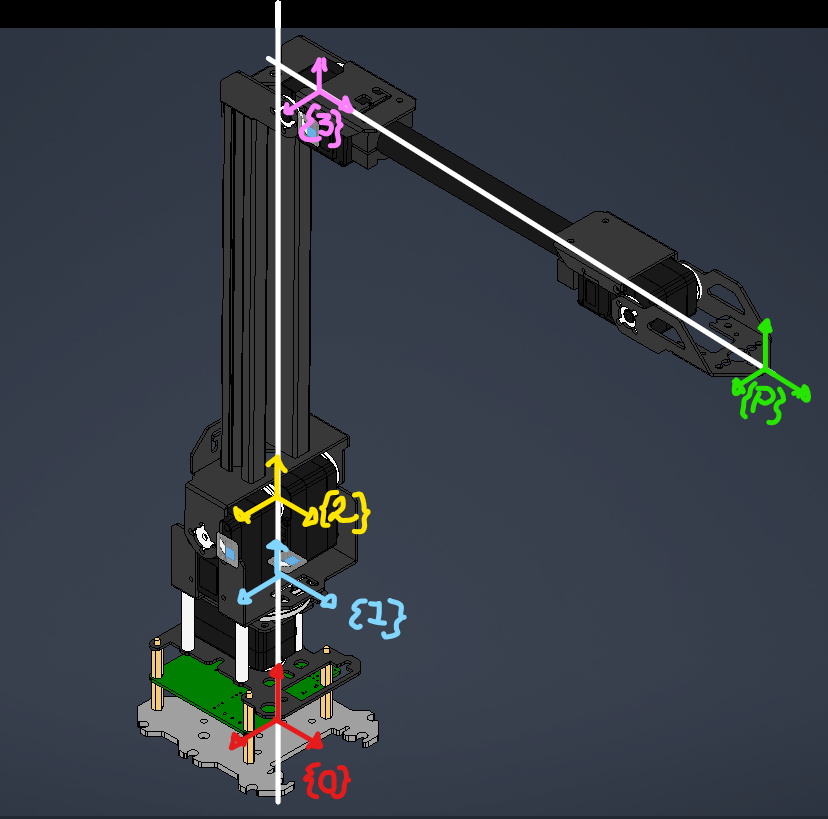

*Imagen 1: Diagrama de coordenadas asignado para el RoArm*

## Trasformada homogenea

En robótica, para describir la posición y orientación de un eslabón respecto a otro se utilizan las **transformadas homogéneas**, que son matrices de 4×4 que combinan en una sola operación tanto la rotación como la traslación entre dos sistemas de referencia consecutivos.

En este proyecto se define una función simbólica general `Tij` que recibe seis parámetros: las traslaciones en X, Y y Z, y los ángulos de rotación gamma (γ), beta (β) y alfa (α), siguiendo la convención de rotaciones **ZYX** (también conocida como ángulos de Euler). La matriz resultante tiene la forma:

%T = | R  p |
%    | 0  1 |

Donde **R** es la matriz de rotación 3×3 que describe la orientación relativa entre dos eslabones, y **p** es el vector de posición 3×1 que indica la traslación entre sus orígenes.

Esta función es la piedra angular de todo el proyecto, ya que será reutilizada a lo largo del código para construir todas las transformadas entre eslabones, calcular las posiciones de los centros de masa, y derivar tanto el modelo cinemático como el dinámico del robot. Cada vez que se llame a `Tij` con parámetros específicos, se estará describiendo cómo se mueve y rota un eslabón respecto al anterior.

syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

% Homogeneous transform
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelado de la posición del robot 3R

Una vez definida la transformada homogénea general, se procede a construir el modelo de posición del robot. Para ello se definen dos tipos de variables simbólicas:

- **Parámetros geométricos:** `z_O_1`, `z_1_2`, `z_2_3`, `z_3_P`, que representan las distancias entre articulaciones consecutivas a lo largo del eje Z de cada eslabón. Estos valores corresponden a las longitudes físicas medidas del robot RoArm.

- **Grados de libertad:** `theta_O_1`, `theta_1_2`, `theta_2_3`, que son los ángulos de rotación de cada articulación y constituyen las coordenadas generalizadas del sistema. Estos son los valores que cambian durante el movimiento del robot.

Con estas variables se construyen las transformadas homogéneas individuales entre cada par de eslabones consecutivos:

syms z_O_1 z_1_2 z_2_3 z_3_P  %parametros
syms theta_O_1 theta_1_2 theta_2_3 %grados de libertad
%T_O_1 → rotación en Z (cintura)
T_O_1 = Tij(0,0,z_O_1,0,0,theta_O_1)

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & 0\\ 0 & 0 & 1 & z_{O,1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_1_2 → rotación en Y (hombro)
T_1_2 = Tij(0,0,z_1_2,0,theta_1_2,0)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & 0 & \sin\left(\theta_{1,2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1,2}\right) & 0 & \cos\left(\theta_{1,2}\right) & z_{1,2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_2_3 → rotación en Y (codo)
T_2_3 = Tij(0,0,z_2_3,0,theta_2_3,0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & z_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_3_P → traslación pura hacia el efector final
T_3_P = Tij(0,0,z_3_P,0,0,0)

$$T\_3\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{3,P}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Nótese que la primera articulación rota sobre el eje Z porque es la que permite girar horizontalmente al robot (cintura), mientras que las articulaciones 2 y 3 rotan sobre el eje Y porque generan movimiento en el plano vertical (elevación del brazo).

Finalmente, la transformada total del robot desde la base hasta el efector final se obtiene multiplicando encadenadamente todas las transformadas individuales:

%T_O_P = T_O_1 · T_1_2 · T_2_3 · T_3_P
T_O_P = simplify(T_O_1*T_1_2*T_2_3*T_3_P)

$$T\_O\_P = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & \sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right)\,\sigma_{1}\\ \cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right)\,\sigma_{1}\\ -\sin\left(\theta_{1,2}+\theta_{2,3}\right) & 0 & \cos\left(\theta_{1,2}+\theta_{2,3}\right) & z_{1,2}+z_{O,1}+z_{3,P}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right) \end{array}$$

Esta matriz 4×4 contiene toda la información necesaria para conocer en cualquier instante dónde se encuentra el efector final del robot y con qué orientación, dados los ángulos de las tres articulaciones. A partir de ella se extrae el **vector de postura** `xi_O_P` que resume en 6 componentes la posición (x, y, z) y orientación del efector, y el **vector de posición** `p_O_P` que contiene únicamente las coordenadas cartesianas del efector final.

**Vector de postura**

xi_O_P = [T_O_P(1,4); T_O_P(2,4); T_O_P(3,4); T_O_P(1,1); T_O_P(2,2); T_O_P(3,3)]

$$xi\_O\_P = \left(\begin{array}{c} \cos\left(\theta_{O,1}\right)\,\left(z_{3,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)\\ \sin\left(\theta_{O,1}\right)\,\left(z_{3,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)\\ z_{1,2}+z_{O,1}+z_{3,P}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{O,1}\right)\\ \cos\left(\theta_{O,1}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}\right)$$


p_O_P = [T_O_P(1,4); T_O_P(2,4); T_O_P(3,4)]

$$p\_O\_P = \left(\begin{array}{c} \cos\left(\theta_{O,1}\right)\,\left(z_{3,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)\\ \sin\left(\theta_{O,1}\right)\,\left(z_{3,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)\\ z_{1,2}+z_{O,1}+z_{3,P}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right) \end{array}\right)$$

## Modelo cinemático directo de las velocidades

Conocer la posición del efector final en función de los ángulos articulares es útil, pero en la práctica también es necesario relacionar las **velocidades articulares** (qué tan rápido giran los motores) con la **velocidad del efector final** (qué tan rápido se mueve la herramienta en el espacio). Esta relación la establece el **Jacobiano geométrico** J(θ).

El Jacobiano es una matriz de 3×3 que se obtiene diferenciando el vector de posición del efector `p_O_P` respecto a cada una de las coordenadas generalizadas:

**v_efector = J(θ) · θ**̇

donde:

v_efector → velocidad cartesiana del efector [3×1]

J(θ)      → matriz Jacobiana              [3×3]

θ̇         → velocidades articulares       [3×1]

**Calculo del Jacobino**

En el código se calcula usando la función `jacobian` de MATLAB, que realiza automáticamente todas las derivadas parciales simbólicas.


%J_theta = simplify(jacobian(xi_O_P,[theta_O_1,theta_1_2, theta_2_3]))
J_theta = simplify(jacobian(p_O_P, [theta_O_1, theta_1_2, theta_2_3]));

**Determinante del Jacobiano**

Un resultado particularmente importante es el **determinante de J(θ)**. Este valor indica si el robot se encuentra en una **configuración singular**, es decir, una posición en la que el robot pierde la capacidad de moverse en alguna dirección del espacio, sin importar qué tan rápido giren sus motores. Matemáticamente esto ocurre cuando:

det(J(θ)) = 0  →  configuración singular  ️

det(J(θ)) ≠ 0  →  configuración regular   

Las singularidades son críticas en el diseño de trayectorias del robot porque en esas configuraciones el control se vuelve inestable y pueden generarse velocidades articulares infinitas.

det(J_theta)

$$ans = \begin{array}{l} \cos\left(\theta_{1,2}\right)\,{z_{2,3}}^{2}\,z_{3,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\,{\cos\left(\theta_{O,1}\right)}^{2}\,\sin\left(\theta_{1,2}\right)+\cos\left(\theta_{1,2}\right)\,{z_{2,3}}^{2}\,z_{3,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{1,2}\right)\,{\sin\left(\theta_{O,1}\right)}^{2}-\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,{z_{2,3}}^{2}\,z_{3,P}\,{\cos\left(\theta_{O,1}\right)}^{2}\,{\sin\left(\theta_{1,2}\right)}^{2}-\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,{z_{2,3}}^{2}\,z_{3,P}\,{\sin\left(\theta_{1,2}\right)}^{2}\,{\sin\left(\theta_{O,1}\right)}^{2}+\cos\left(\theta_{1,2}\right)\,z_{2,3}\,{z_{3,P}}^{2}\,\sigma_{1}\,{\cos\left(\theta_{O,1}\right)}^{2}+\cos\left(\theta_{1,2}\right)\,z_{2,3}\,{z_{3,P}}^{2}\,\sigma_{1}\,{\sin\left(\theta_{O,1}\right)}^{2}-\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,z_{2,3}\,{z_{3,P}}^{2}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\,{\cos\left(\theta_{O,1}\right)}^{2}\,\sin\left(\theta_{1,2}\right)-\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,z_{2,3}\,{z_{3,P}}^{2}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{1,2}\right)\,{\sin\left(\theta_{O,1}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\theta_{1,2}+\theta_{2,3}\right)}^{2} \end{array}$$

### Modelo cinemático inverso de las velocidades

La pseudoinversa del Jacobiano se presenta  como referencia para el modelo cinemático  inverso de velocidades. Su cálculo simbólico  completo queda fuera del alcance de este  proyecto debido a su complejidad computacional,  sin embargo su formulación es:si

%J_theta_psin = pinv(J_theta)

## Modelo dinámico del robot en el espacio

El modelo dinámico es la parte central del proyecto. A diferencia del modelo cinemático que solo describe **dónde está** y **cómo se mueve** el robot, el modelo dinámico responde a la pregunta fundamental del control: **¿cuánta fuerza o par debe aplicar cada motor para lograr un movimiento deseado?**

Para obtener este modelo se utiliza el **formalismo de Euler-Lagrange**, que es un enfoque energético basado en dos conceptos:

Energía cinética  K → energía del movimiento

Energía potencial U → energía almacenada por gravedad

Lagrangeano: L = K - U

**Cálculo de los Centros de Masa de los Eslabones**

Para cada eslabón se define una transformada homogénea adicional `T_i_Ci` que ubica el centro de masa del eslabón i respecto a su propia articulación, usando los valores `z_1_C1`, `z_2_C2`, `z_3_C3` obtenidos y corregidos del robot RoArm. Combinando esta transformada con las del modelo cinemático se obtiene la posición de cada centro de masa respecto al marco inercial de la base `p_O_Ci`. Finalmente, las velocidades lineales de cada centro de masa `v_O_Ci` se obtienen diferenciando su posición respecto a cada coordenada generalizada activa.

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3 z_1_C1 z_2_C2 z_3_C3

T_1_C1 = Tij(0,0,z_1_C1,0,0,0)

$$T\_1\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{1,\mathrm{C1}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_C1 = simplify(T_O_1*T_1_C1);

p_O_C1 = [T_O_C1(1,4); T_O_C1(2,4); T_O_C1(3,4)]

$$p\_O\_C1 = \left(\begin{array}{c} 0\\ 0\\ z_{1,\mathrm{C1}}+z_{O,1} \end{array}\right)$$


v_O_C1 = diff(p_O_C1, theta_O_1)*theta_dot_O_1 

$$v\_O\_C1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

%

T_2_C2 = Tij(0,0,z_2_C2,0,0,0)

$$T\_2\_C2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{2,\mathrm{C2}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_C2 = simplify(T_O_1*T_1_2*T_2_C2);

p_O_C2 = [T_O_C2(1,4); T_O_C2(2,4); T_O_C2(3,4)]

$$p\_O\_C2 = \left(\begin{array}{c} z_{2,\mathrm{C2}}\,\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\\ z_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\\ z_{1,2}+z_{O,1}+z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right) \end{array}\right)$$


v_O_C2 = diff(p_O_C2, theta_O_1)*theta_dot_O_1 + diff(p_O_C2, theta_1_2)*theta_dot_1_2

$$v\_O\_C2 = \left(\begin{array}{c} {\dot{\theta }}_{1,2}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-{\dot{\theta }}_{O,1}\,z_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{1,2}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+{\dot{\theta }}_{O,1}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\\ -{\dot{\theta }}_{1,2}\,z_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}\right) \end{array}\right)$$


%

T_3_C3 = Tij(0,0,z_3_C3,0,0,0)

$$T\_3\_C3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{3,\mathrm{C3}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_C3 = simplify(T_O_1*T_1_2*T_2_3*T_3_C3);

p_O_C3 = [T_O_C3(1,4); T_O_C3(2,4); T_O_C3(3,4)]

$$p\_O\_C3 = \left(\begin{array}{c} \cos\left(\theta_{O,1}\right)\,\left(z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)\\ \sin\left(\theta_{O,1}\right)\,\left(z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)\\ z_{1,2}+z_{O,1}+z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right) \end{array}\right)$$


v_O_C3 = diff(p_O_C3, theta_O_1)*theta_dot_O_1 + diff(p_O_C3, theta_1_2)*theta_dot_1_2 + diff(p_O_C3, theta_2_3)*theta_dot_2_3

$$v\_O\_C3 = \begin{array}{l} \left(\begin{array}{c} {\dot{\theta }}_{1,2}\,\cos\left(\theta_{O,1}\right)\,\sigma_{2}-{\dot{\theta }}_{O,1}\,\sin\left(\theta_{O,1}\right)\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{1,2}\,\sin\left(\theta_{O,1}\right)\,\sigma_{2}+{\dot{\theta }}_{O,1}\,\cos\left(\theta_{O,1}\right)\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{O,1}\right)\\ -{\dot{\theta }}_{1,2}\,\sigma_{1}-{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{2}=z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right) \end{array}$$

**Propagación de las Velocidades Angulares**

Las velocidades angulares de cada eslabón no se pueden obtener simplemente diferenciando posiciones, ya que están expresadas en marcos de referencia distintos. Por ello se utiliza el método de propagación, que parte de la base con velocidad angular cero y va acumulando la contribución de cada articulación usando las matrices de rotación inversas entre eslabones. Los vectores `nu_1`, `nu_2`, `nu_3` indican el eje de giro de cada articulación en su propio marco de referencia:

nu_1 = [0;0;1] → cintura gira sobre Z

nu_2 = [0;1;0] → antebrazo gira sobre Y

nu_3 = [0;1;0] → brazo gira sobre Y

% Matrices de Rotación

R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(2,3); T_O_1(2,1),T_O_1(1,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)];
R_1_O = transpose(R_O_1)

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(2,3); T_1_2(2,1),T_1_2(1,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)];
R_2_1 = transpose(R_1_2)

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & 0 & -\sin\left(\theta_{1,2}\right)\\ 0 & 0 & 0\\ 0 & 0 & \cos\left(\theta_{1,2}\right) \end{array}\right)$$


R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(2,3); T_2_3(2,1),T_2_3(1,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)];
R_3_2 = transpose(R_2_3)

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & 0 & -\sin\left(\theta_{2,3}\right)\\ 0 & 0 & 0\\ 0 & 0 & \cos\left(\theta_{2,3}\right) \end{array}\right)$$


% calculo de las velocidades angulares
omega_O_O = [0;0;0];
nu_1 = [0;0;1];
omega_1_1 = R_O_1*omega_O_O + nu_1*theta_dot_O_1

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$


nu_2 = [0;1;0];
omega_2_2 = R_2_1*omega_1_1 + nu_2*theta_dot_1_2

$$omega\_2\_2 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}\right)\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right) \end{array}\right)$$


nu_3 = [0;1;0];
omega_3_3 = R_3_2*omega_2_2 + nu_3*theta_dot_2_3

$$omega\_3\_3 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{2,3}\right)-{\dot{\theta }}_{O,1}\,\cos\left(\theta_{2,3}\right)\,\sin\left(\theta_{1,2}\right)\\ {\dot{\theta }}_{2,3}\\ {\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{2,3}\right) \end{array}\right)$$

**Matrices de Inercia**

Las matrices de inercia de cada eslabón se definen como matrices diagonales 3×3, asumiendo que los ejes del modelo coinciden con los ejes principales de inercia de cada pieza. Los valores de la diagonal `Ixx`, `Iyy`, `Izz` fueron obtenidos directamente de Inventor para cada eslabón del robot RoArm.

syms I_xx1 I_yy1 I_zz1 I_xx2 I_yy2 I_zz2 I_xx3 I_yy3 I_zz3

I_C1 = [I_xx1, 0, 0; 0, I_yy1, 0; 0, 0, I_zz1]

$$I\_C1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}} & 0 & 0\\ 0 & I_{\mathrm{yy1}} & 0\\ 0 & 0 & I_{\mathrm{zz1}} \end{array}\right)$$

I_C2 = [I_xx2, 0, 0; 0, I_yy2, 0; 0, 0, I_zz2]

$$I\_C2 = \left(\begin{array}{ccc} I_{\mathrm{xx2}} & 0 & 0\\ 0 & I_{\mathrm{yy2}} & 0\\ 0 & 0 & I_{\mathrm{zz2}} \end{array}\right)$$

I_C3 = [I_xx3, 0, 0; 0, I_yy3, 0; 0, 0, I_zz3]

$$I\_C3 = \left(\begin{array}{ccc} I_{\mathrm{xx3}} & 0 & 0\\ 0 & I_{\mathrm{yy3}} & 0\\ 0 & 0 & I_{\mathrm{zz3}} \end{array}\right)$$

**Cálculo del Lagrangeano**

Con todos los elementos anteriores se calculan las energías del sistema. La energía cinética de cada eslabón tiene dos componentes, la traslacional asociada al movimiento de su centro de masa, y la rotacional asociada a su velocidad angular. La energía potencial de cada eslabón depende de la altura de su centro de masa respecto al plano de referencia. El Lagrangeano total es la diferencia entre la suma de energías cinéticas y la suma de energías potenciales.

syms m_1 m_2 m_3 g

% energía cinetica
k_1 = 1/2*m_1*transpose(v_O_C1)*v_O_C1 + transpose(omega_1_1)*I_C1*omega_1_1

$$k\_1 = I_{\mathrm{zz1}}\,{{\dot{\theta }}_{O,1}}^{2}$$

k_2 = 1/2*m_2*transpose(v_O_C2)*v_O_C2 + transpose(omega_2_2)*I_C2*omega_2_2

$$k\_2 = I_{\mathrm{yy2}}\,{{\dot{\theta }}_{1,2}}^{2}+\frac{m_{2}\,{\left({\dot{\theta }}_{1,2}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+{\dot{\theta }}_{O,1}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{\theta }}_{O,1}\,z_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)-{\dot{\theta }}_{1,2}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)\right)}^{2}}{2}+I_{\mathrm{zz2}}\,{{\dot{\theta }}_{O,1}}^{2}\,{\cos\left(\theta_{1,2}\right)}^{2}+I_{\mathrm{xx2}}\,{{\dot{\theta }}_{O,1}}^{2}\,{\sin\left(\theta_{1,2}\right)}^{2}+\frac{m_{2}\,{{\dot{\theta }}_{1,2}}^{2}\,{z_{2,\mathrm{C2}}}^{2}\,{\sin\left(\theta_{1,2}\right)}^{2}}{2}$$

k_3 = 1/2*m_3*transpose(v_O_C3)*v_O_C3 + transpose(omega_3_3)*I_C1*omega_3_3

$$k\_3 = \begin{array}{l} \frac{m_{3}\,{\left({\dot{\theta }}_{1,2}\,\cos\left(\theta_{O,1}\right)\,\sigma_{2}-{\dot{\theta }}_{O,1}\,\sin\left(\theta_{O,1}\right)\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{O,1}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{\theta }}_{1,2}\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{\theta }}_{1,2}\,\sin\left(\theta_{O,1}\right)\,\sigma_{2}+{\dot{\theta }}_{O,1}\,\cos\left(\theta_{O,1}\right)\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{O,1}\right)\right)}^{2}}{2}+I_{\mathrm{yy1}}\,{{\dot{\theta }}_{2,3}}^{2}+I_{\mathrm{xx1}}\,{\left({\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{2,3}\right)+{\dot{\theta }}_{O,1}\,\cos\left(\theta_{2,3}\right)\,\sin\left(\theta_{1,2}\right)\right)}^{2}+I_{\mathrm{zz1}}\,{{\dot{\theta }}_{O,1}}^{2}\,{\cos\left(\theta_{1,2}\right)}^{2}\,{\cos\left(\theta_{2,3}\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{2}=z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right) \end{array}$$

% energía potencial
g_O = [0;0;-g];

u_1 = -m_1*transpose(p_O_C1)*g_O

$$u\_1 = g\,m_{1}\,\left(z_{1,\mathrm{C1}}+z_{O,1}\right)$$

u_2 = -m_2*transpose(p_O_C2)*g_O

$$u\_2 = g\,m_{2}\,\left(z_{1,2}+z_{O,1}+z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\right)$$

u_3 = -m_3*transpose(p_O_C3)*g_O

$$u\_3 = g\,m_{3}\,\left(z_{1,2}+z_{O,1}+z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)\right)$$

% lagrangeano

L = (k_1+k_2+k_3)-(u_1+u_2+u_3)

**Cálculo de los Pares Generalizados**

Aplicando las ecuaciones de Euler-Lagrange a cada coordenada generalizada se obtienen los pares `tao_1`, `tao_2`, `tao_3`. Cada par se calcula en dos pasos: primero se deriva el Lagrangeano respecto a la velocidad articular correspondiente `D_i = ∂L/∂θ̇ᵢ`, y luego se aplica la ecuación completa de Lagrange expandida mediante la regla de la cadena para obtener la derivada total respecto al tiempo.

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

D_1 = diff(L,theta_dot_O_1)


tao_1 = (diff(D_1,theta_O_1)*theta_dot_O_1 + diff( ...
    D_1,theta_1_2)*theta_dot_1_2 + diff( ...
    D_1,theta_2_3)*theta_dot_2_3 + diff( ...
    D_1,theta_dot_O_1)*theta_ddot_O_1 + diff( ...
    D_1,theta_dot_1_2)*theta_ddot_1_2 + diff( ...
    D_1,theta_dot_2_3)*theta_ddot_2_3) - diff(L,theta_O_1)



D_2 = diff(L,theta_dot_1_2)

$$D\_2 = \begin{array}{l} 2\,I_{\mathrm{yy2}}\,{\dot{\theta }}_{1,2}+m_{3}\,\sigma_{1}\,\left({\dot{\theta }}_{1,2}\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\right)+m_{3}\,\cos\left(\theta_{O,1}\right)\,\sigma_{2}\,\left({\dot{\theta }}_{1,2}\,\cos\left(\theta_{O,1}\right)\,\sigma_{2}-{\dot{\theta }}_{O,1}\,\sin\left(\theta_{O,1}\right)\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{O,1}\right)\right)+m_{3}\,\sin\left(\theta_{O,1}\right)\,\sigma_{2}\,\left({\dot{\theta }}_{1,2}\,\sin\left(\theta_{O,1}\right)\,\sigma_{2}+{\dot{\theta }}_{O,1}\,\cos\left(\theta_{O,1}\right)\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{O,1}\right)\right)+m_{2}\,{\dot{\theta }}_{1,2}\,{z_{2,\mathrm{C2}}}^{2}\,{\sin\left(\theta_{1,2}\right)}^{2}-m_{2}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)\,\left({\dot{\theta }}_{O,1}\,z_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)-{\dot{\theta }}_{1,2}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)\right)+m_{2}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\,\left({\dot{\theta }}_{1,2}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+{\dot{\theta }}_{O,1}\,z_{2,\mathrm{C2}}\,\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{2}=z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right) \end{array}$$

tao_2 = (diff(D_2,theta_O_1)*theta_dot_O_1 + diff( ...
    D_2,theta_1_2)*theta_dot_1_2 + diff( ...
    D_2,theta_2_3)*theta_dot_2_3 + diff( ...
    D_2,theta_dot_O_1)*theta_ddot_O_1 + diff( ...
    D_2,theta_dot_1_2)*theta_ddot_1_2 + diff( ...
    D_2,theta_dot_2_3)*theta_ddot_2_3) - diff(L,theta_1_2)


D_3 = diff(L,theta_dot_2_3)

$$D\_3 = \begin{array}{l} 2\,I_{\mathrm{yy1}}\,{\dot{\theta }}_{2,3}+m_{3}\,z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\left({\dot{\theta }}_{1,2}\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\right)+m_{3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{O,1}\right)\,\left({\dot{\theta }}_{1,2}\,\cos\left(\theta_{O,1}\right)\,\sigma_{2}-{\dot{\theta }}_{O,1}\,\sin\left(\theta_{O,1}\right)\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{O,1}\right)\right)+m_{3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{O,1}\right)\,\left({\dot{\theta }}_{1,2}\,\sin\left(\theta_{O,1}\right)\,\sigma_{2}+{\dot{\theta }}_{O,1}\,\cos\left(\theta_{O,1}\right)\,\sigma_{1}+{\dot{\theta }}_{2,3}\,z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{O,1}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{2}=z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right) \end{array}$$

tao_3 = (diff(D_3,theta_O_1)*theta_dot_O_1 + diff( ...
    D_3,theta_1_2)*theta_dot_1_2 + diff( ...
    D_3,theta_2_3)*theta_dot_2_3 + diff( ...
    D_3,theta_dot_O_1)*theta_ddot_O_1 + diff( ...
    D_3,theta_dot_1_2)*theta_ddot_1_2 + diff( ...
    D_3,theta_dot_2_3)*theta_ddot_2_3) - diff(L,theta_2_3)

**Extracción de las Matrices Dinámicas**

El vector de pares `tau` contiene mezcladas las contribuciones de inercia, Coriolis y gravedad. Para separar cada matriz se realizan sustituciones selectivas: se igualan a cero todos los términos excepto el que interesa. Para obtener cada columna de M(q) se activa una aceleración articular a la vez con velocidades y gravedad en cero. Para V(q,q̇) se activan las velocidades articulares con aceleraciones y gravedad en cero. Para G(q) se activa únicamente la gravedad con velocidades y aceleraciones en cero.

% Vector de par

tau = collect([tao_1; tao_2; tao_3],[m_1,m_2,m_3, theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3])


M_1 = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[1, 0, 0,0, 0, 0,0])

$$M\_1 = \begin{array}{l} \left(\begin{array}{c} 2\,I_{\mathrm{zz1}}+m_{3}\,\left({\cos\left(\theta_{O,1}\right)}^{2}\,\sigma_{1}+{\sin\left(\theta_{O,1}\right)}^{2}\,\sigma_{1}\right)+2\,I_{\mathrm{xx1}}\,{\left(\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{2,3}\right)+\cos\left(\theta_{2,3}\right)\,\sin\left(\theta_{1,2}\right)\right)}^{2}+m_{2}\,\left({z_{2,\mathrm{C2}}}^{2}\,{\cos\left(\theta_{O,1}\right)}^{2}\,{\sin\left(\theta_{1,2}\right)}^{2}+{z_{2,\mathrm{C2}}}^{2}\,{\sin\left(\theta_{1,2}\right)}^{2}\,{\sin\left(\theta_{O,1}\right)}^{2}\right)+2\,I_{\mathrm{zz2}}\,{\cos\left(\theta_{1,2}\right)}^{2}+2\,I_{\mathrm{xx2}}\,{\sin\left(\theta_{1,2}\right)}^{2}+2\,I_{\mathrm{zz1}}\,{\cos\left(\theta_{1,2}\right)}^{2}\,{\cos\left(\theta_{2,3}\right)}^{2}\\ 0\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)}^{2} \end{array}$$

M_2 = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[0, 1, 0,0, 0, 0,0])

$$M\_2 = \begin{array}{l} \left(\begin{array}{c} 0\\ 2\,I_{\mathrm{yy2}}+m_{2}\,\left({z_{2,\mathrm{C2}}}^{2}\,{\cos\left(\theta_{1,2}\right)}^{2}\,{\cos\left(\theta_{O,1}\right)}^{2}+{z_{2,\mathrm{C2}}}^{2}\,{\cos\left(\theta_{1,2}\right)}^{2}\,{\sin\left(\theta_{O,1}\right)}^{2}+{z_{2,\mathrm{C2}}}^{2}\,{\sin\left(\theta_{1,2}\right)}^{2}\right)+m_{3}\,\left({\sigma_{2}}^{2}+{\cos\left(\theta_{O,1}\right)}^{2}\,{\sigma_{1}}^{2}+{\sin\left(\theta_{O,1}\right)}^{2}\,{\sigma_{1}}^{2}\right)\\ m_{3}\,\left(z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sigma_{1}\,{\cos\left(\theta_{O,1}\right)}^{2}+z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sigma_{1}\,{\sin\left(\theta_{O,1}\right)}^{2}+z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\sigma_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)\\ \sigma_{2}=z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right) \end{array}$$

M_3 = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[0, 0, 1,0, 0, 0,0])

$$M\_3 = \begin{array}{l} \left(\begin{array}{c} 0\\ m_{3}\,\left(z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sigma_{1}\,{\cos\left(\theta_{O,1}\right)}^{2}+z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sigma_{1}\,{\sin\left(\theta_{O,1}\right)}^{2}+z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\left(z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)\right)\\ 2\,I_{\mathrm{yy1}}+m_{3}\,\left({z_{3,\mathrm{C3}}}^{2}\,\sigma_{2}\,{\cos\left(\theta_{O,1}\right)}^{2}+{z_{3,\mathrm{C3}}}^{2}\,\sigma_{2}\,{\sin\left(\theta_{O,1}\right)}^{2}+{z_{3,\mathrm{C3}}}^{2}\,{\sin\left(\theta_{1,2}+\theta_{2,3}\right)}^{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)\\ \sigma_{2}={\cos\left(\theta_{1,2}+\theta_{2,3}\right)}^{2} \end{array}$$


M_q = collect([M_1 M_2 M_3],[m_1,m_2,m_3])


V_q = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[0, 0, 0,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,0])

G_q = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[0, 0, 0,0, 0, 0,g])

$$G\_q = \left(\begin{array}{c} 0\\ -g\,m_{3}\,\left(z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\right)-g\,m_{2}\,z_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}\right)\\ -g\,m_{3}\,z_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}\right)$$

## Declaración de Parámetros y Evaluación Numérica en la Configuración de Referencia

**Implementación Numérica y Configuración de Referencia**

En esta sección se consolidan los valores numéricos reales obtenidos y corregidos del robot RoArm en el Sistema Internacional. El bloque inicial define las masas, longitudes entre ejes articulados, centros de masa locales y momentos principales de inercia de los tres eslabones dinámicamente activos (cintura, antebrazo y el conjunto unificado brazo-gripper).

Para validar la consistencia física del formalismo matemático implementado, se define un vector de prueba para la configuración de referencia (Home Position), donde todas las posiciones articulares $(\theta_i)
$ y velocidades articulares $(\dot{\theta}_i)$ se establecen en cero. Utilizando el comando subs, se reemplazan de manera simultánea tanto las constantes físicas como las variables de estado articulares, empleando finalmente la función double para forzar la conversión de las expresiones simbólicas a matrices numéricas de doble precisión $(M(q_0), V(q_0, 0)     ,  G(q_0))$.

%% 1. Primero se declaran todos los valores numéricos
m1_val = 0.214;
m2_val = 0.448;
m3_val = 0.304;

z_O_1_val = 0.085;
z_1_2_val = 0.039;
z_2_3_val = 0.234;
z_3_P_val = 0.284;

z_1_C1_val = 0.067155;
z_2_C2_val = 0.081682;
z_3_C3_val = 0.083936;

I_xx1_val = 0.000068;
I_yy1_val = 0.000166;
I_zz1_val = 0.000137;

I_xx2_val = 0.002115;
I_yy2_val = 0.002187;
I_zz2_val = 0.00016;

I_xx3_val = 0.002431;
I_yy3_val = 0.002447;
I_zz3_val = 0.000052;

g_val = 9.81;

%% 2. Luego los valores de articulaciones
theta_O_1_val = 0;
theta_1_2_val = 0;
theta_2_3_val = 0;
theta_dot_O_1_val = 0;
theta_dot_1_2_val = 0;
theta_dot_2_3_val = 0;

%% 3. Y al final la sustitución
params_sym = [m_1, m_2, m_3, ...
              z_O_1, z_1_2, z_2_3, z_3_P, ...
              z_1_C1, z_2_C2, z_3_C3, ...
              I_xx1, I_yy1, I_zz1, ...
              I_xx2, I_yy2, I_zz2, ...
              I_xx3, I_yy3, I_zz3, g, ...
              theta_O_1, theta_1_2, theta_2_3];

params_val = [m1_val, m2_val, m3_val, ...
              z_O_1_val, z_1_2_val, z_2_3_val, z_3_P_val, ...
              z_1_C1_val, z_2_C2_val, z_3_C3_val, ...
              I_xx1_val, I_yy1_val, I_zz1_val, ...
              I_xx2_val, I_yy2_val, I_zz2_val, ...
              I_xx3_val, I_yy3_val, I_zz3_val, g_val, ...
              theta_O_1_val, theta_1_2_val, theta_2_3_val];

params_sym_v = [params_sym, ...
                theta_dot_O_1, theta_dot_1_2, theta_dot_2_3];

params_val_v = [params_val, ...
                theta_dot_O_1_val, theta_dot_1_2_val, theta_dot_2_3_val];

M_q_num = double(subs(M_q, params_sym, params_val))

M_q_num =     0.0009         0         0
         0    0.0381    0.0081
         0    0.0081    0.0025


V_q_num = double(subs(V_q, params_sym_v, params_val_v))

V_q_num =      0
     0
     0


G_q_num = double(subs(G_q, params_sym, params_val))

G_q_num =      0
     0
     0


Los resultados V(q₀,0) = 0 y G(q₀) = 0 son  físicamente coherentes: cuando el robot está  completamente vertical con θ = 0, no existen  fuerzas de Coriolis ni pares gravitacionales  en esa configuración particular.

## Sustitución Parcial de Parámetros Físicos

**Obtención del Modelo Dinámico Semisimbólico**

En el desarrollo de sistemas de control y simulación de trayectorias, evaluar numéricamente todo el sistema en cada instante de tiempo puede ser computacionalmente ineficiente. Por ello, en esta etapa se realiza una sustitución selectiva: se inyectan únicamente los parámetros que permanecen constantes durante la operación del robot (masas, longitudes, inercias y la aceleración de la gravedad *g*), dejando las posiciones, velocidades y aceleraciones articulares como variables puramente simbólicas.

Este procedimiento genera un modelo intermedio o "semisimbólico". Las matrices resultantes dejan de ser expresiones universales para transformarse en las ecuaciones dinámicas específicas y exclusivas de la estructura del robot RoArm analizado.

%% Sustitución solo de parámetros físicos (sin thetas)
params_sym_fis = [m_1, m_2, m_3, ...
                  z_O_1, z_1_2, z_2_3, z_3_P, ...
                  z_1_C1, z_2_C2, z_3_C3, ...
                  I_xx1, I_yy1, I_zz1, ...
                  I_xx2, I_yy2, I_zz2, ...
                  I_xx3, I_yy3, I_zz3, g];

params_val_fis = [m1_val, m2_val, m3_val, ...
                  z_O_1_val, z_1_2_val, z_2_3_val, z_3_P_val, ...
                  z_1_C1_val, z_2_C2_val, z_3_C3_val, ...
                  I_xx1_val, I_yy1_val, I_zz1_val, ...
                  I_xx2_val, I_yy2_val, I_zz2_val, ...
                  I_xx3_val, I_yy3_val, I_zz3_val, g_val];

M_q_sim = subs(M_q, params_sym_fis, params_val_fis)

V_q_sim = subs(V_q, params_sym_fis, params_val_fis)

G_q_sim = subs(G_q, params_sym_fis, params_val_fis)

$$G\_q\_sim = \left(\begin{array}{c} 0\\ -\frac{48890097\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)}{195312500}-\frac{7436757108138357984849\,\sin\left(\theta_{1,2}\right)}{7036874417766400000000}\\ -\frac{48890097\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)}{195312500} \end{array}\right)$$

## Optimización y Simplificación Simbólica Completa

**Simplificación Algebraica de las Matrices Dinámicas**

Dado que las ecuaciones diferenciales de movimiento derivadas del formalismo de Euler-Lagrange suelen contener una alta densidad de términos trigonométricos acoplados (productos de senos y cosenos debidos a las rotaciones encadenadas), el modelo semisimbólico en bruto puede resultar redundante.

Para resolver esto, se ejecuta este último bloque empleando la función simplify. MATLAB aplica identidades trigonométricas algebraicas para reducir el modelo a su mínima expresión posible. El resultado final son las matrices dinámicas$ $M(q)_{sim}$, $V(q, \dot{q})_{sim}$ y $G(q)_{sim}$$ optimizadas computacionalmente, expresadas como funciones compactas y elegantes que dependen única y exclusivamente del estado articular del manipulador. Estas expresiones son la base fundamental para el posterior diseño de algoritmos de control robusto, como el control por torque computado.

%% Sustitución de parámetros físicos (thetas quedan simbólicas)
params_sym_fis = [m_1, m_2, m_3, ...
                  z_O_1, z_1_2, z_2_3, z_3_P, ...
                  z_1_C1, z_2_C2, z_3_C3, ...
                  I_xx1, I_yy1, I_zz1, ...
                  I_xx2, I_yy2, I_zz2, ...
                  I_xx3, I_yy3, I_zz3, g];

params_val_fis = [m1_val, m2_val, m3_val, ...
                  z_O_1_val, z_1_2_val, z_2_3_val, z_3_P_val, ...
                  z_1_C1_val, z_2_C2_val, z_3_C3_val, ...
                  I_xx1_val, I_yy1_val, I_zz1_val, ...
                  I_xx2_val, I_yy2_val, I_zz2_val, ...
                  I_xx3_val, I_yy3_val, I_zz3_val, g_val];

M_q_sim = simplify(subs(M_q, params_sym_fis, params_val_fis))

$$M\_q\_sim = \begin{array}{l} \left(\begin{array}{ccc} \frac{5054407876196417\,\cos\left(2\,\theta_{2,3}\right)}{73786976294838206464}-\frac{7418246059802494831109790370669466831\,\cos\left(2\,\theta_{1,2}\right)}{633825300114114700748351602688000000000}-\frac{5830929\,\cos\left(2\,\theta_{1,2}+\theta_{2,3}\right)}{976562500}+\frac{5054407876196417\,\cos\left(2\,\theta_{1,2}-2\,\theta_{2,3}\right)}{147573952589676412928}-\frac{4974803683993828740652421007\,\cos\left(2\,\theta_{1,2}+2\,\theta_{2,3}\right)}{4503599627370496000000000000000}+\sigma_{1}+\frac{134428472597827271965202607686434073415239}{9903520314283042199192993792000000000000000} & 0 & 0\\ 0 & \frac{5830929\,\cos\left(\theta_{2,3}\right)}{488281250}+\frac{129491567721157175682316560679714073415239}{4951760157141521099596496896000000000000000} & \sigma_{1}+\frac{130722451}{61035156250}\\ 0 & \sigma_{1}+\frac{130722451}{61035156250} & \frac{1392601183678394204511249783}{562949953421312000000000000000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{5830929\,\cos\left(\theta_{2,3}\right)}{976562500} \end{array}$$

V_q_sim = simplify(subs(V_q, params_sym_fis, params_val_fis))

G_q_sim = simplify(subs(G_q, params_sym_fis, params_val_fis))

$$G\_q\_sim = \left(\begin{array}{c} 0\\ -\frac{48890097\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)}{195312500}-\frac{7436757108138357984849\,\sin\left(\theta_{1,2}\right)}{7036874417766400000000}\\ -\frac{48890097\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)}{195312500} \end{array}\right)$$

## Conclusión:

En el presente trabajo se desarrolló de manera integral el modelo dinámico de un manipulador robótico de tres grados de libertad (3R), partiendo de la obtención de sus propiedades físicas a partir de un modelo tridimensional desarrollado en Autodesk Inventor. A lo largo del proyecto se logró extraer información relevante de cada uno de los eslabones, como masas, centros de gravedad y momentos de inercia, permitiendo establecer una conexión directa entre el modelo mecánico del robot y su representación matemática.

Como parte del desarrollo matemático, se construyó el modelo cinemático del manipulador mediante transformadas homogéneas, obteniendo la posición y orientación del efector final en función de las variables articulares. Asimismo, se formuló el modelo cinemático de velocidades mediante el cálculo del Jacobiano, lo que permitió relacionar las velocidades articulares con la velocidad del efector final e identificar las configuraciones singulares del sistema, información fundamental para el análisis y control del robot.

Posteriormente, se desarrolló el modelo dinámico utilizando el formalismo de Euler-Lagrange. A partir de las posiciones de los centros de masa, las velocidades lineales y angulares de cada eslabón, y las propiedades inerciales obtenidas del modelo CAD, fue posible formular las ecuaciones de movimiento completas del robot. Como resultado, se obtuvieron las matrices dinámicas fundamentales del sistema: la matriz de inercia, el vector de fuerzas de Coriolis y centrífugas, y el vector de fuerzas gravitacionales, los cuales describen de manera completa el comportamiento dinámico del robot. De la misma forma se comprobó la congruencia en los resultados obtenidos para una configuración singular en la que \theta = 0 (configuración de referencia): los vectores de Coriolis y centrífugas resultan nulos debido a que las velocidades articulares fueron establecidas en cero. También, el vector gravitacional se anuló en esta misma configuración debido a que los centros de masa se encuentran alineados con los ejes de rotación, por lo que el peso de los eslabones no genera momentos gravitacionales sobre las articulaciones

Cabe mencionar que durante el proceso de obtención de parámetros se identificó un aspecto particular: los centros de gravedad reportados por el software estaban referenciados al origen global del ensamble y no a los sistemas de coordenadas locales de cada articulación. Esto hizo necesario realizar una traslación analítica de los centros de masa para expresarlos correctamente en los marcos de referencia del modelo dinámico. Esta corrección resultó ser esencial para mantener coherencia en los resultados, evidenciando la importancia de una adecuada definición de marcos de referencia en proyectos de Robótica.

La implementación del modelo en MATLAB permitió trabajar con expresiones simbólicas generales y posteriormente sustituir los parámetros reales del robot para obtener un modelo dinámico específico del manipulador en cuestión. Además, la evaluación numérica realizada en la configuración de referencia permitió verificar la coherencia física de los resultados obtenidos, validando así el procedimiento seguido durante el desarrollo del proyecto.

Finalmente, puedo decir que, el desarrollo de este trabajo permitió cumplir satisfactoriamente con el objetivo de obtener los parámetros físicos de un robot modelado en Inventor e integrarlos en un modelo dinámico completo en MATLAB. Más allá de la obtención de las ecuaciones matemáticas, el proyecto permitió comprender la importancia de la caracterización física de un robot manipulador y la influencia que tienen sus propiedades mecánicas sobre su comportamiento dinámico.

**Referencias**

- Spong, M. W., Hutchinson, S., & Vidyasagar, M. (2006). *Robot Modeling and Control*. John Wiley & Sons.

- Craig, J. J. (2005). *Introduction to Robotics: Mechanics and Control* (3rd ed.). Pearson Prentice Hall.

- Siciliano, B., Sciavicco, L., Villani, L., & Oriolo, G. (2009). *Robotics: Modelling, Planning and Control*. Springer.

- MathWorks. (2024). *Symbolic Math Toolbox Documentation*. The MathWorks, Inc. Recuperado de [https://www.mathworks.com/help/symbolic/](https://www.mathworks.com/help/symbolic/)

- Autodesk. (2024). *Autodesk Inventor Professional - Physical Properties*. Autodesk, Inc. Recuperado de [https://www.autodesk.com/products/inventor/](https://www.autodesk.com/products/inventor/)

- Peña Medina, E. (2025). *Introducción al Modelado Espacial de Robots* [Material de clase]. Facultad de Ingeniería, Universidad Nacional Autónoma de México.